# How much radiant flux has my 100 lm LED?

Julius Muschaweck, July 9, 2025

To use this Matlab live script, several routines from my Matlab Spectrum Library are required.

Open source, free download at [https://github.com/JuliusMuschaweck/JMO_Spectrum](https://github.com/JuliusMuschaweck/JMO_Spectrum)

We consider a white LED with about 4000K color temperature.

A typical spectrum is this:

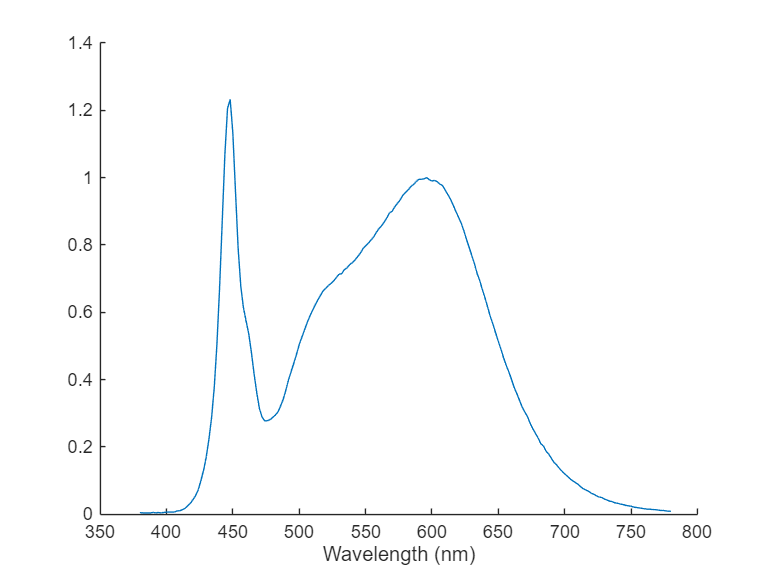

clear;
whiteSpectrum = ReadLightToolsSpectrumFile('LED_4003K.sre');
figure(); clf; hold on;
PlotSpectrum(whiteSpectrum);

The spectrum has arbitrary units. But assuming we get 100 lm with this spectrum, what is the radiant flux?

To answer, we need the spectral luminous efficacy of this spectrum: How many lumens per Watt?

Let's assume this spectrum is given in W/nm. Then, its radiant flux is simply the integral over wavelength. The `IntegrateSpectrum` function of my library does that:

radiantFlux = IntegrateSpectrum(whiteSpectrum);
fprintf("radiant flux = %0.1f W",radiantFlux);

radiant flux = 175.6 W

To compute the luminous flux, we must weight with the VLambda curve and multiply with the 683 lm/W constant from the SI unit definitions:

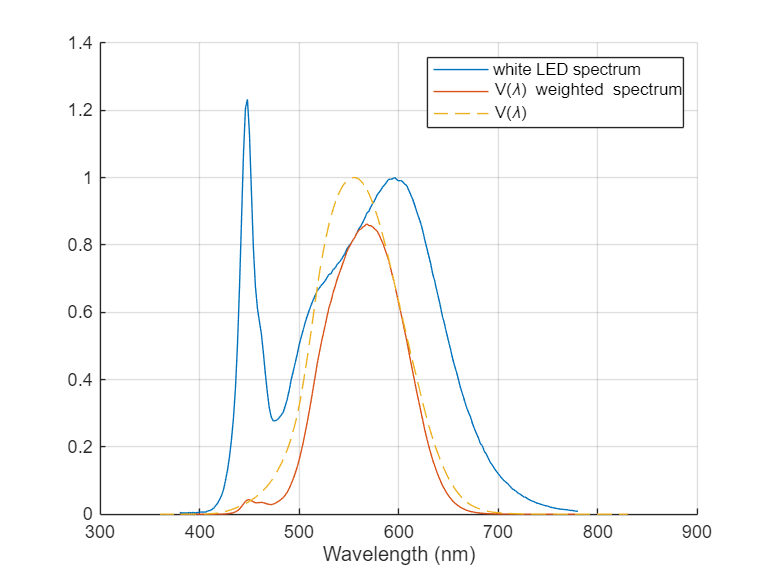

figure(); clf; hold on; grid on;
ax = gca; 
VLambdaWeightedSpectrum = MultiplySpectra(whiteSpectrum, Vlambda());
PlotSpectrum(whiteSpectrum);
PlotSpectrum(VLambdaWeightedSpectrum);
PlotSpectrum(Vlambda(),'--');
legend({"white LED spectrum","V(\lambda) weighted spectrum","V(\lambda)"})

luminousFlux = 683 * IntegrateSpectrum(VLambdaWeightedSpectrum);
fprintf("luminous flux = %0.1f lm",luminousFlux);

luminous flux = 57646.0 lm

Now, efficacy is luminous flux divide by radiant flux. The original spectrum normalization is unimportant, any scaling factor cancels.

efficacy = luminousFlux / radiantFlux;
fprintf("spectral efficacy = %0.1f lm/W",efficacy);

spectral efficacy = 328.3 lm/W

And the radiant flux is now

LEDradiantFlux_at_100lm = 100 / efficacy;
fprintf("LED radiant flux at 100 lm luminous flux = %0.3f W",LEDradiantFlux_at_100lm);

LED radiant flux at 100 lm luminous flux = 0.305 W